# Progetto di Robust Control - Benchmark problem

Si è scelto di risolvere il problema (SEMPLIFICATO) di controllo robusto discusso al seguente paper:

 [(PDF) Benchmark Problem for Robust Control Design](https://www.researchgate.net/publication/220045505_Benchmark_Problem_for_Robust_Control_Design)

Al fine di avere un sistema SISO ed evitare le complicazioni di sistema MIMO, **è stato scelto di trascurare il disturbo w2 **(che dal punto di vista del problema completo, vuol dire non reiettarlo).

**Nota: **il problema 1 sarà il problema il più commentato e completo. Successivamente, saranno discusse negli altri problemi solo considerazioni ulteriori.

**Nota: **previa diversa indicazione, le variabili sono espresse in unità di misura standard (kg, m, N*m ecc..)

**Nota: **trovi le sottofunzioni utilizzate durante il progetto nell'ultima section.

**Nota: **trovi la refence github all'ultima section

## Introduzione e presentazione del problema

Il **sistema meccanico** è il seguente

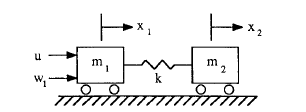

che può essere descritto dalla seguente **i-s-u**

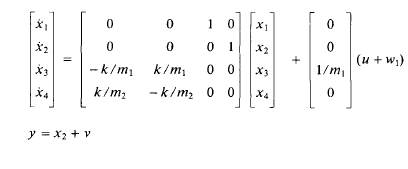

dove, i **segnali** rappresentano:

- x1, x2 sono la posizione delle masse

- x3, x4 sono le velocità delle masse

- u è il controllo sul corpo m1 (forza)

- y è la misura del sensore di posizione, che misura x2

- w1 è il disturbo sulle masse m1 (derivante ad esempio dall'attuatore).

- v è il rumore di misura

L'**obiettivo** è: controllare x2

**Approccio adottato: **

Si adotterà il seguente approccio metodico:

- 1) Si progetterà il controllore sul nominale con Hinf

- 2) Viene fatto un check sulla stabilità robusta

- 3) Viene fatto un check sulle prestazioni robuste

**Modellistica dei disturbi: **

- w1 verrà modellato come un disturbo in catena diretta, a monte del sistema.

- v rumore di misura verrà modellato come disturbo in catena di retroazione

%parametri del rumore
f_inf_rads = 200; 
pw_n = 1e-9;

dt = 0.01; %tempo di campionamento simulink

tol_mm = 3;

Abbiamo un modello di rumore bianco + filtro passa alto e un modello di sinusoidi casuali, entrambi i casi a frequenza maggiore di f_inf_rad_s. 

Il rumore è stato modellato per non aver mai ampiezza maggiore di 1e-3, che vuol dire avere un buon sensore con tolleranza 1mm

In serie a questo blocco sarà inserita un gain con tolleranza in mm, che può amplificare questo rumore per testare il rumore per sensori differenti.

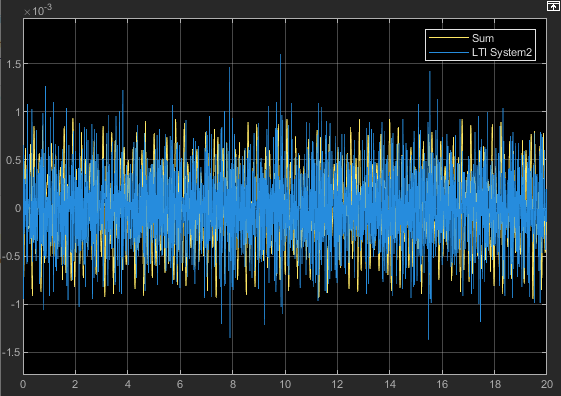

## Forma TITO

Sui **segnali **adottiamo la seguente scelta progettuale

- w1, w2, w3 saranno rispettivamente w1 (della traccia), v errore di misura ed r riferimento

- z1 e z2 saranno rispettivamente l'errore y (da portare a 0 per controllare yz) e il controllo u per non avere un controllo troppo costoso.

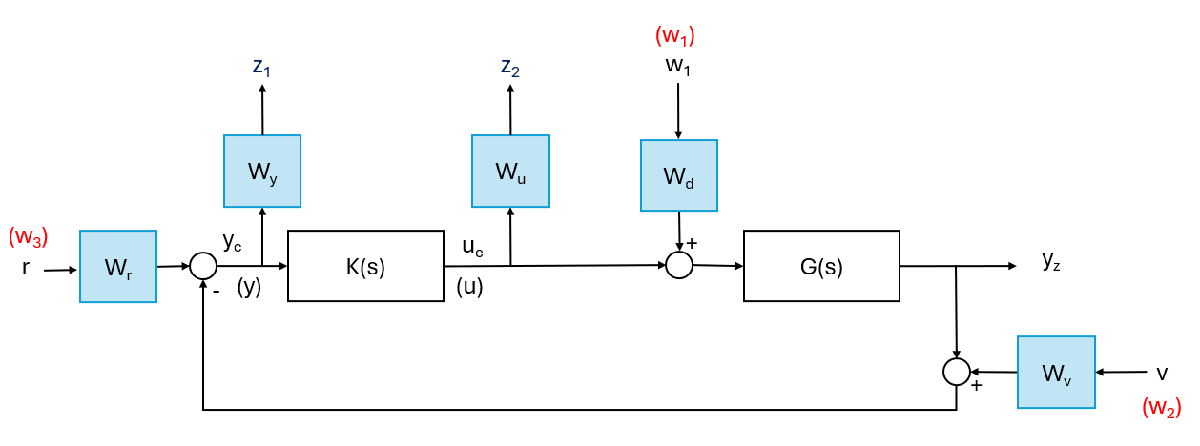

La **matrice P(s)** è stata calcolata (a mano):

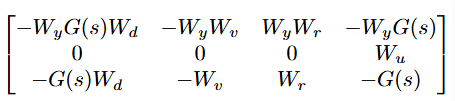

# Problema 1

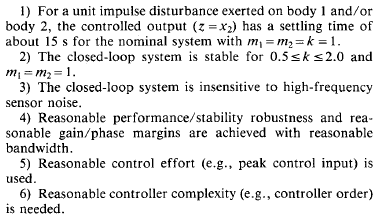

In pratica è richiesto 

- sul nominale, che un gradino unitario di disturbo venga reiettato in un tempo di assestamento di 15s 

- che il sistema sia robusto al parametro d'incertezza k

In entrambi i casi, sono richieste le seguenti performance a ciclo chiuso:

- insensibilità al rumore di misura ad alta frequenza

- buoni margini di robustezza

- controllo ragionevole

- complessità del controllore ragionevole

NOTA: Per la specifica 1, ricorda che stiamo considerando il problema semplificato, quindi consideriamo il disturbo applicabile solo sul corpo m1.

### Definizione sistema per problema 1

%parametri
m1 = 1

m1 = 1

m2 = 1

m2 = 1

%k = ureal('k', 1, 'Range', [0.5 2])       %NON RIUSCITO
k = ureal('k', 1, 'PlusMinus', 0.5)        %TROVATO PER QUESTO 

Uncertain real parameter "k" with nominal value 1 and variability [-0.5,0.5].
Block Properties



%sistema
G = defG(m1, m2, k);
G_nom = minreal(G.Nominal);

### Definizione ingresso disturbante

%parametri del disturbo
amp_dis =  1;
step_time_dis = 0.2;


prepariamo il simulink per tale caso

set_input_Sim(0, 0, amp_dis, step_time_dis, 0, 0, 0, pw_n);

### Progetto Hinf (senza pensare alla robustezza)

Realizziamo il progetto Hinf sul nominale, seguendo la specifca dell'assestamento dei 15 secondi.

%pesi
Wd = 10* makeweight(10, [1 1], 0);                              %passa basso 
Wv = 0.01 * makeweight(0, [f_inf_rads  sqrt(2)/2], 1);          %passa alto
Wr = 1;                                                      
Wy = 1;                     
Wu = 0.5;

%progetto Hinf
P = minreal(TITO(G_nom, Wd, Wr, Wv, Wy, Wu));

14 states removed.



kinf = tf(minreal(hinfsyn(P, 1, 1)))


kinf =
 
  97.37 s^5 + 1.953e04 s^4 + 1.131e04 s^3 + 3.937e04 s^2 + 2.112e04 s + 5463
  --------------------------------------------------------------------------
  s^6 + 206.7 s^5 + 1375 s^4 + 4925 s^3 + 1.161e04 s^2 + 1.863e04 s + 213.5
 
Continuous-time transfer function.
Model Properties


Simuliamo la risposta a gradino unitario di disturbo, con lieve rumore

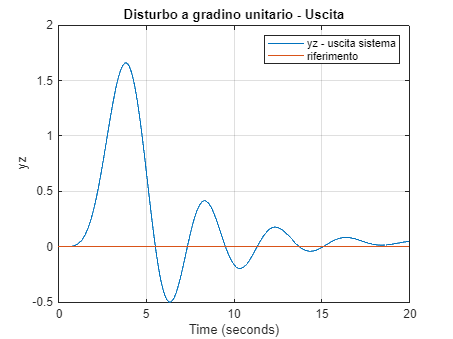

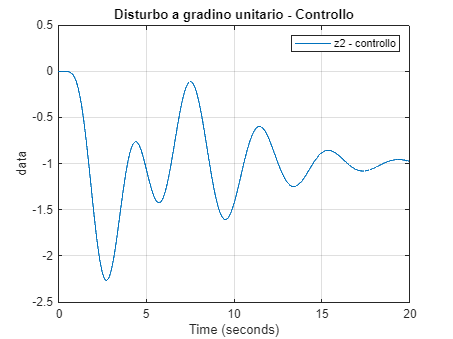

%imposto i parametri della simulazione (nota: disturbo già settato)
set_k_Sim(kinf);
set_G_Sim(G_nom);

%lancio la simulazione
simulazione(20, 'Disturbo a gradino unitario', [1 0 1]);

Il sistema nominalmente fa quanto richiesto, **si assesta in meno di 15 sec dopo il gradino**.

Ovviamente, ho fatto il progetto senza tener conto della robustezza, dunque non mi aspetto un sistema robusto. Verifichiamolo

verifica_stab_robusta(G, kinf);

stabmarg = struct with fields:
           LowerBound: 0.1321
           UpperBound: 0.1321
    CriticalFrequency: 1.8815


wcu = struct with fields:
    k: 1.0660


Come previsto, **non ho margini di robustezza** (stabmarg<1). 

### Aggiunta - cerca della M11 dallo schema a blocchi (richiesto dal docente)

M11 trovata da lftdata

Cloop = feedback(G*kinf, 1);
M11_lftdata = minreal(get_M11_Delta_blk(Cloop))


M11_lftdata =
 
             -s^7 - 6.754 s^6 - 24.34 s^5 - 106.3 s^4 - 120.9 s^3 - 99.23 s^2 - 52.72 s - 13.66
  ---------------------------------------------------------------------------------------------------------
  s^9 + 6.754 s^8 + 26.34 s^7 + 71.11 s^6 + 141.8 s^5 + 213.6 s^4 + 241.9 s^3 + 198.5 s^2 + 105.4 s + 27.32
 
Continuous-time transfer function.


M11 trovata da schema a blocchi (vedi [./CalcoloM11_schemablocchi.pdf](matlab:open('./CalcoloM11_schemablocchi.pdf')))

% Definizione della variabile s per scrivere fdt a mano
s = tf('s');

M11_mano = minreal(-0.5 * (2*(s^2)+kinf)/(s^4+2*s^2+kinf))


M11_mano =
 
                   -s^9 - 406.7 s^8 - 4.272e04 s^7 - 2.8e05 s^6 - 1.016e06 s^5 - 4.3e06 s^4 - 4.877e06 s^3 - 3.99e06 s^2 - 2.114e06 s - 5.463e05
  ----------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 406.7 s^10 + 4.272e04 s^9 + 2.808e05 s^8 + 1.082e06 s^7 + 2.901e06 s^6 + 5.758e06 s^5 + 8.642e06 s^4 + 9.753e06 s^3 + 7.98e06 s^2 + 4.228e06 s + 1.093e06
 
Continuous-time transfer function.


Le due funzioni sembrano differenti, nelle fdt, ma in realtà questo è dovuto ad approssimazioni e calcoli numerici. Infatti se tracciamo Bode delle due funzioni questi sono perfettamente sovrapponibili, il che vuol dire che** sono la stessa funzione**.

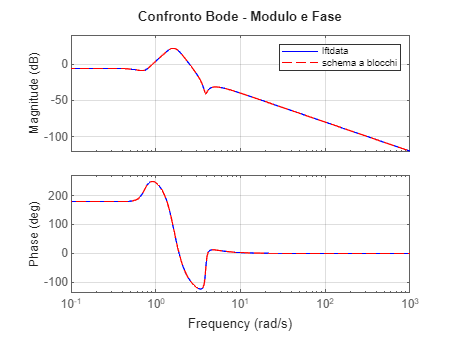

figure;
bode(M11_lftdata, 'b', M11_mano , 'r--');  % blu per G1, rosso tratteggiato per G2
grid on;
legend('lftdata', 'schema a blocchi');
title('Confronto Bode - Modulo e Fase');

### Progetto robusto

Per ottenere la stabilità robusta devo modificare i pesi e rifare il progetto Hinf

%pesi
Wd = 2000 * makeweight(10, [1 1], 0);                           %passa basso 
Wv = 0.01 * makeweight(0, [f_inf_rads  sqrt(2)/2], 1);          %passa alto da frequenza rumorosa
Wr = 0.001;                                                      
Wy = 50;                     
Wu = 15 ;

%progetto Hinf
P = minreal(TITO(G_nom, Wd, Wr, Wv, Wy, Wu));

14 states removed.



kinf = tf(minreal(hinfsyn(P, 1, 1)))


kinf =
 
  3.206e05 s^5 + 6.478e07 s^4 + 1.309e08 s^3 + 2.629e08 s^2 + 2.653e08 s + 1.334e08
  ---------------------------------------------------------------------------------
   s^6 + 80.01 s^5 + 3004 s^4 + 7.008e04 s^3 + 1.093e06 s^2 + 1.084e07 s + 1.57e05
 
Continuous-time transfer function.
Model Properties


Questi sono i pesi trovati che mi danno la stabilità robusta, possiamo vederlo alla prossima section

### Verifica della stabilità robusta

Questi sono i pesi che mi danno robustezza se messi nel caso semplificato k in [0.5, 1.5].

stabmarg = struct with fields:
           LowerBound: 1.0039
           UpperBound: 1.0039
    CriticalFrequency: 1.9730


wcu = struct with fields:
    k: 0.4980


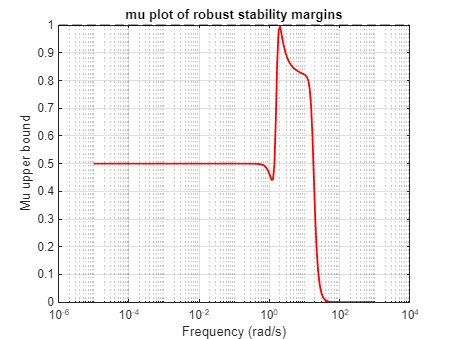

verifica_stab_robusta(G, kinf, true)

**La norma mu è sotto 1, quindi abbiamo la robustezza.**

**Nota:** il caso non semplificato k in [0.5, 2] richiesto dalla traccia, risulta tale per cui si debbarinunciare troppo alle prestazioni nominali quindi si è scelto un trade off ad un'incertezza minore.

### Verifica delle prestazioni nominali

Prima di ragionare sulle prestazioni robuste, è chiaro che bisogna controllare quelle nominali. Le verifica delle stesse, nei precedenti punti, è stata fatta empiricamente dalle simulazioni. 

Non abbiamo fatto controlli in termini di norma, ma questo è necessario per le robuste, quindi **traduciamo i requisiti in termini di norma infinito**.

Definiamo le **funzioni di sensitività**:

S_nom = tf(minreal(feedback(1, G_nom*kinf)));             %sensività diretta
F_nom = tf(minreal(feedback(1, G_nom*kinf)*G_nom*kinf));  %sensività inversa o complementare

10 states removed.


Q_nom = tf(minreal(feedback(1, G_nom*kinf)*kinf));        %sensività del controllo

6 states removed.


Le relazioni (tralasciando eventuali segni '-') tra i vari segnali sono:

%rispetto all'errore yc
Tz1w1_nom = minreal(tf(G_nom)*S_nom);            %funzione tra 'z1(yc)' e'w1(d)'
Tz1w2_nom = F_nom;                               %funzione tra 'z1(yc)' e'w2(n)'

%rispetto al controllo (non verranno studiate)
% Tz2w1_nom = minreal(tf(G_nom)*Q_nom);            %funzione tra 'z2(u)' e 'w1(d)'
% Tz2w2_nom = Q_nom;                               %funzione tra 'z2(u)' e 'w2(n)' 

**Nota: **abbiamo voluamente ignorato il riferimento, perché non è un segnale di nostro interesse in questo punto del problema (si considera nullo).

**Nota:** Un'altra considerazione che ci permette di semplificare il problema, è che il controllo già sappiamo essere spropositato e rumoroso: lo capiamo dalla scelta dei pesi per garantire la robustezza. Quindi lo assumiamo ideale e analizziamo solo le prestazioni dinamiche del sistema (yc)

Definisco **pesi limite prestazionali:**

- Tz1w1 vorrei fosse un passa alto (perché il gradino è a basse frequenze)

- Tz1w2 vorrei fosse un passa basso (perché il rumore vive ad alte frequenze, dopo f_inf_rads)

Dopo averli scelti, verifichiamo che diano dei comportamenti soddisfacenti

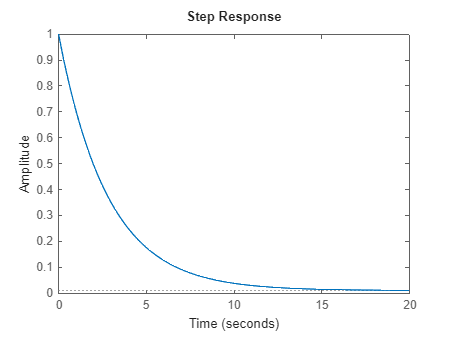

%per d
Tz1w1_desiderato_max = makeweight(0.01, [0.35 1*0.7], 1); 
xaxes = 0:0.1:20;
figure;
step(Tz1w1_desiderato_max, xaxes);

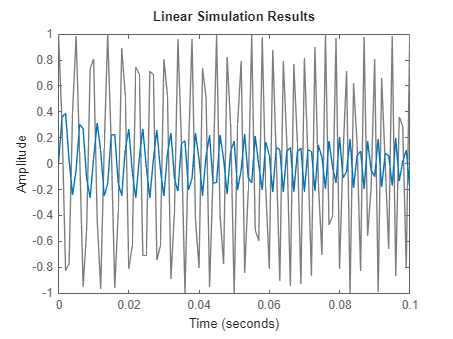


%per v/n
Tz1w2_desiderato_max = makeweight(2, [f_inf_rads 2*0.7], 0.01);
t = 0:0.001:0.1;
f0 = f_inf_rads; % Frequenza iniziale
f1 = f_inf_rads*2; % Frequenza finale
u = chirp(t, f0, 0.1, f1);
lsim(Tz1w2_desiderato_max, u, t);

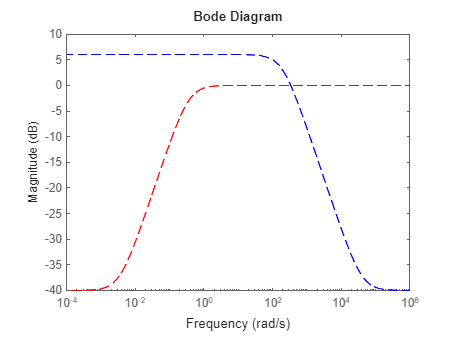


%scelta
bodemag(Tz1w1_desiderato_max, "r--", Tz1w2_desiderato_max,"b--");

Il sistema Tz1w1_desiderato_max risponde al gradino in un tempo di assestamento di circa 15s. 

Il sistema Tz1w2_desiderato_max risponde al rumore riducendolo di 1/3 d'intensità, che ci soddisfa abbastanza.

Dalla teoria, abbiamo fondamentalmente **due modi per verificare che le prestazioni nominali siano rispettate**:

- Traccio i diagrammi di Bode e vedo se la mia funzione Tzw sta sotto Tzw_desiderato_max per tutte le frequenze o almeno quelle che m'interessa

- Posso normalizzare Tzw scegliendo l'inversa di  Tzw_desiderato_max come funzione di peso e vedere se la norma infinito è <1   (**Ricorda:**  MiaFunzione < Desiderata  ->  Desiderata^(-1)*MiaFunzione < 1 )

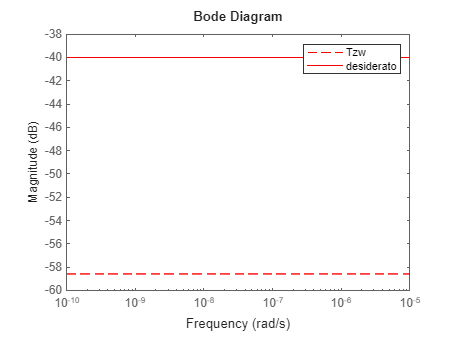

%1° MODO
bodemag(Tz1w1_nom, "r--", Tz1w1_desiderato_max, "r") %per Tz1w1
legend("Tzw", "desiderato");

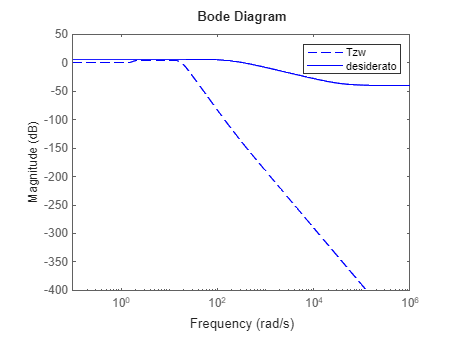


bodemag(Tz1w2_nom, "b--", Tz1w2_desiderato_max, "b") %per Tz1w2
legend("Tzw", "desiderato");


%2° MODO
Wpd = (tf(minreal(Tz1w1_desiderato_max)))^(-1);        
Wpv = (tf(minreal(Tz1w2_desiderato_max)))^(-1);

norm(minreal(Wpd * Tz1w1_nom), "inf")

ans = 0.1236

norm(minreal(Wpv * Tz1w2_nom), "inf")

ans = 0.8003

Come si vede, le **prestazioni nominali sono soddisfatte**

### Verifica delle prestazioni robuste - tentativo con robgain (non funzionante)

Verifichiamo le robuste con **robgain**. Robgain studia il guadagno di una funzione al variare delle incertezze.

Studiamo per quanta incertezza, le funzioni superano il limite di norma = 1.

%definizione funzioni di prestazioni incerte.
Tz1w1 = G * feedback(1, G * kinf) ;            % S * G   
%Tz1w2 = G * kinf * feedback(1, G * kinf);      % F (non usato)

%posso anche pensare ad un limite ulteriore se voglio un livello di tolleranza
norma_limite = 1;

%istruzioni matlab
opt = robOptions('Display','on');
[perfmarg,wcu] = robgain(minreal(Wpd * minreal(Tz1w1)), norma_limite,opt)

2 states removed.
The performance margin is 0 since the nominal system is unstable.


perfmarg = struct with fields:
           LowerBound: 0
           UpperBound: 0
    CriticalFrequency: NaN


wcu = struct with fields:
    k: 1


8 states removed.
The performance margin is 0 since the nominal gain exceeds 1.


perfmarg = struct with fields:
           LowerBound: 0
           UpperBound: 0
    CriticalFrequency: NaN


wcu = struct with fields:
    k: 1


**Problema:** In questo caso robgain mi dà problemi, perché il minreal per gli uss è conservativo, ovvero non elimina dei zeri/poli sull'asse immaginario che invece vengono eliminati se il minreal viene fatto nel caso nominale. Dunque, mi dice che il sistema nominale è instabile, perché non sono state fatte quelle cancellazioni.

Il motivo è che questi potrebbero essere associati a degli effetti destabilizzanti per alcune incertezze, ma noi abbiamo già verificato la stabilità robusta ed è garantita, quindi non abbiamo questo problema.

**Non sono riuscito a risolvere**, ovvero a trovare un modo per forzare robgain, quindi cambiamo approccio e limitiamo a fare uno studio in frequenza, su una serie di campioni, nella prossima section.

### Verifica delle prestazioni robuste - tentativo studio in frequenza

Prendiamo una serie di campioni delle funzioni di peso incerte e verichiamo su Bode se stanno o non stanno sotto la funzione desiderata

Per Tz1w1

Tz1w1 = G * feedback(1, G * kinf) ;            % S * G incerta

% Numero di campioni
N = 5;
Tz1w1_samples = usample(Tz1w1, N); % Estraggo N campioni
w = {1e-5 1e2};

% Bode
figure;
hold on;

% Colore per il sistema certo
bodemag(Tz1w1_desiderato_max, w, 'k');  % 'k' = nero

% Ciclo su tutti i campioni incerti
for i = 1:N
    bodemag(minreal(Tz1w1_samples(:, :, i)), w, 'r--'); % rosso tratteggiato   
end

4 states removed.
4 states removed.
4 states removed.
4 states removed.
4 states removed.


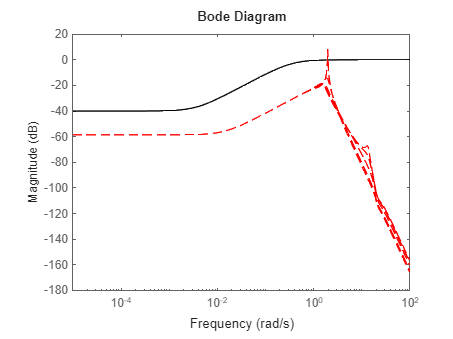


hold off;

Come si vede in alcune simulazioni, c'è qualche funzione che va leggermente sopra la mia funzione desiderata. Dunque **non ho la certezza di avere performance robuste nel senso stringente del termine**.

Tuttavia, **questo caso limite potrebbe essere influente**, soprattutto dato che il gradino è un ingresso a frequenza nulla e tale picco ce l'ho per frequenza circa 10rad/s.

**Nota: **Un modo per verificarlo è fare simulazioni con il parametro d'incertezza k che ha causato il problema. Tale dettaglio non verrà trattato, in quanto questo progetto esula dall'andare troppo nello specifico.

Per Tz1w2

%Per Tz1w1
Tz1w2 = G * kinf * feedback(1, G * kinf) ;            % F incerta

% Numero di campioni
N = 5;
Tz1w1_samples = usample(Tz1w2, N); % Estraggo N campioni
w = {1e-1 1e3};

% Bode
figure;
hold on;

% Colore per il sistema certo
bodemag(Tz1w2_desiderato_max, w, 'k');  % 'k' = nero

% Ciclo su tutti i campioni incerti
for i = 1:N
    bodemag(minreal(Tz1w1_samples(:, :, i)), w, 'r--'); % rosso tratteggiato   
end

10 states removed.
10 states removed.
10 states removed.
10 states removed.
10 states removed.


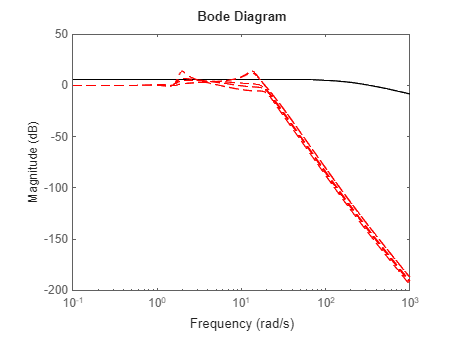


hold off;

Come si vede in alcune simulazioni, c'è qualche funzione che va leggermente sopra la mia funzione desiderata. 

Tuttavia, il rumore  in ingresso a tale funzione vive come stabilito da 200rad/s in poi e in quella banda d'interesse, la funzione rossa (incerta) è ampiamente sotto la nera.

**Quindi ho in tal caso prestazioni robuste nel range di frequenze di mio interesse.**

### Simulazione finale

Simuliamo il sistema incerto e verifichiamo che rimane stabile e che le performance sono di fatto simili a quelle sul nominale.

%il controllore su simulink lo settiamo noi, mentre G verrà campionato
%sulle incertezze e settato diversamente dalla funzione simulazione incerta
set_k_Sim(kinf);
simulazione_incerta(20, 'Disturbo a gradino unitario (sis.inc.)', G, 5);


### Riduzione d'ordine

Provo a ridurre d'ordine il controllore

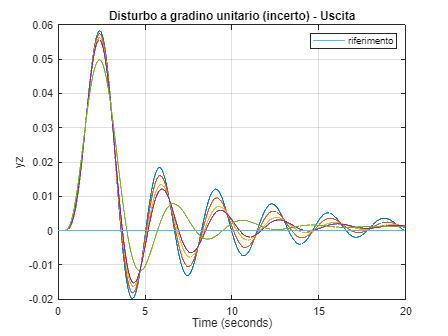

%riduzione
hsv = hsvd(kinf)

kinf_red = riduciControllorePerEnergia(kinf)

%valutazione su se mantiene le proprietà
if ~(order(kinf_red) == order(kinf))

    %stabilità robusta
    verifica_stab_robusta(G, kinf_red);

hsv = 1.0e+04 *

    8.1134
    7.0826
    1.7644
    0.5989
    0.1334
    0.0411


Ordine scelto: 4 (Energia mantenuta: 0.9902)

kinf_red =
 
  -1845 s^4 + 6.419e05 s^3 + 1.878e07 s^2 - 9.127e07 s + 3.293e08
  ---------------------------------------------------------------
        s^4 + 33.57 s^3 + 1478 s^2 + 1.729e04 s + 3.874e05
 
Continuous-time transfer function.
Model Properties


stabmarg = struct with fields:
           LowerBound: 0
           UpperBound: 0
    CriticalFrequency: NaN


wcu = struct with fields:
    k: 1


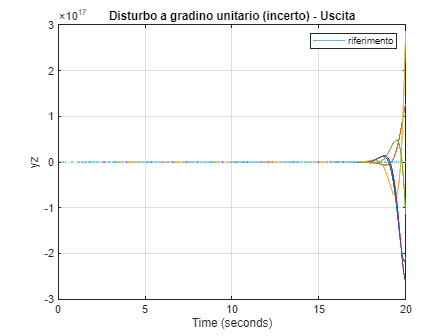

    %simulazioni
    set_k_Sim(kinf_red);
    simulazione_incerta(20, 'Disturbo a gradino unitario (incerto)', G, 5);
end


La riduzione d'ordine mi ha fatto perdere la stabilità robusta! Quindi non l'adotteremo.

#### SOLUZIONE PROBLEMA 1

Il controllore che soddisfa al meglio la nostra richiesta è:

# Problema 2

In questo caso ci sta chiedendo di **massimizzare la robustezza rispetto ai 3 parametri incerti**

Non dando informazioni sul range di m1, m2 e k, stavolta li prendiamo con un'**incertezza normalizzata [0,2] con val nom=1**, in modo che il risultato è espresso indipendentemente dall'ampiezza di tale incertezza e rappresenta una** stima assoluta di robustezza**, non più relativa all'incertezza in gioco. 

### Definizione sistema per problema 2

%parametri
m1 = ureal('m1', 1, 'PlusMinus', 1)   
m2 = ureal('m2', 1, 'PlusMinus', 1)
k = ureal('k', 1, 'PlusMinus', 1)   

%sistema
G = defG(m1, m2, k);
G_nom = minreal(G.Nominal);

### Verifica robustezza controllore precedente

Usiamo il controllore trovato per il problema 1 come base da cui partire.

Verifichiamo quanto sia stabilte robusto date le 3 incertezze.

stabmarg = struct with fields:
           LowerBound: 0.1590
           UpperBound: 0.1593
    CriticalFrequency: 13.5804


wcu = struct with fields:
     k: 1.1593
    m1: 0.8407
    m2: 0.8407


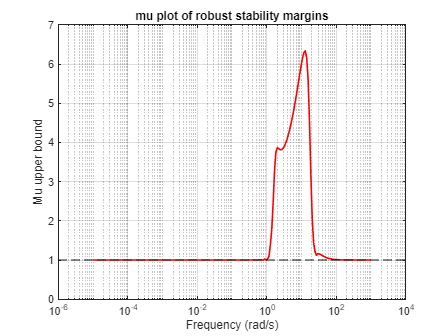

verifica_stab_robusta(G, kinf, true)

Il sistema non è per niente robusto!!

#### SOLUZIONE PROBLEMA 2

Si è provato, giocando con i pesi ad ottenere un margine migliore di quello ottenuto, ma è davvero complicato.

Ovviamente, non si pretende che il sistema sia completamente robusto, perché m1, m2 o k = 0, hanno delle implicazioni molto significative sulla struttura del sistema. Che signifca avere una massa nulla? O una molla con costante elastica nulla? Il sistema perde di controllabilità.

Quindi ci limitiamo a terminare qui la nostra disamina, fornendo semplicemente i margini di robustezza del controllore al punto 1.

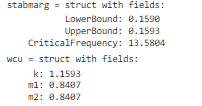

# Problema 3

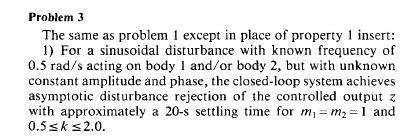

Dunque lo stesso del problema 1, ma stavolta il disturbo d è una sinusoide di frequenza 0.5 rad/s, ma con ampiezza e fase non noti.

La richiesta sul nominale è quella di avere una reiezione entro 20 secondi.

Per il disturbo per semplicità consideriamo un ampiezza random da 0.5 a 2.

### Definizione sistema per problema 3

%parametri
m1 = 1

m1 = 1

m2 = 1

m2 = 1

%k = ureal('k', 1, 'Range', [0.5 2])       %NON RIUSCITO
k = ureal('k', 1, 'PlusMinus', 0.5)        %TROVATO PER QUESTO 

Uncertain real parameter "k" with nominal value 1 and variability [-0.5,0.5].
Block Properties



%sistema
G = defG(m1, m2, k);
G_nom = minreal(G.Nominal);


### Definizione ingresso disturbante

%parametri del disturbo 
amp_dis =  0.5 + (2 - 0.5) * rand       %ampiezza random da 0.5 a 2

amp_dis = 1.7001

ph_dis = (2*pi) * rand                  %fase random da 0 a 2pi

ph_dis = 2.7107

%f_dis_rad_s = 0.5
f_dis_Hz = 0.5 / (2*pi)                 %frequenza in radianti al secondo

f_dis_Hz = 0.0796

prepariamo il simulink per tale caso

set_input_Sim(0, 0, 0, 0, amp_dis, f_dis_Hz, ph_dis, pw_n);

### Progetto sul nominale

Prendiamo a modello il **controllore trovato al problema 1 come punto di partenza. **Modificheremo quei pesi per avvicinarci al controllore desiderato.

In particolare, prima il disturbo w era un gradino, adesso è una sinusoide. Possiamo scegliere un peso apposito a questo disturbo: un **filtro a spillo attorno la sua frequenza**.

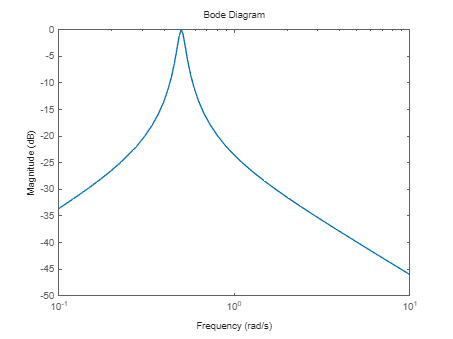

w0 = 2*pi*f_dis_Hz;     % pulsazione
Q  = 10;                % qualità del filtro a spillo che applicherò (più alto = più stretto)

filtro_spillo = tf([0 w0/Q 0], [1 w0/Q w0^2]);      %filtro a spillo attorno w0

%check su filtro
opts = bodeoptions;
opts.PhaseVisible = 'off';          % Disattiva la fase
bodeplot(filtro_spillo, opts);

Per ottenere la stabilità robusta devo modificare i pesi e rifare il progetto Hinf

%pesi
Wd = 30000 * filtro_spillo;                                      %filtro a spillo attorno a frequenza
Wv = 0.01 * makeweight(0, [f_inf_rads  sqrt(2)/2], 1);           %passa alto
Wr = 0.00001;                                                      
Wy = 30;                     
Wu = 10;

%progetto Hinf
P = minreal(TITO(G_nom, Wd, Wr, Wv, Wy, Wu));

15 states removed.



kinf = tf(minreal(hinfsyn(P, 1, 1)))


kinf =
 
    2.476e05 s^6 + 4.996e07 s^5 + 8.9e07 s^4 + 1.899e08 s^3 + 1.753e08 s^2 + 9.003e07 s + 3.37
  -----------------------------------------------------------------------------------------------
  s^7 + 70.47 s^6 + 2485 s^5 + 5.587e04 s^4 + 8.489e05 s^3 + 8.226e06 s^2 - 1.862e06 s + 3.911e06
 
Continuous-time transfer function.


Il sistema si comporta così sul nominale:

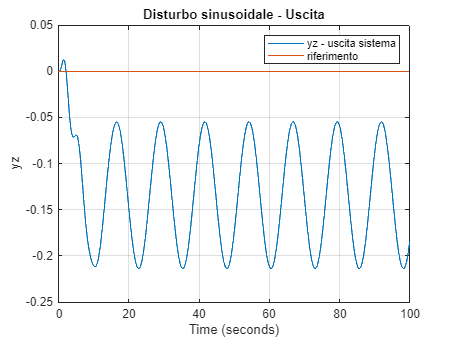

%imposto i parametri della simulazione (nota: disturbo già settato)
set_k_Sim(kinf);
set_G_Sim(G_nom);

%lancio la simulazione
simulazione(100, 'Disturbo sinusoidale', [1 0 0]);

Il sistema deamplfifica il disturbo all'ordine dei centimetri. Si potrebbe fare di meglio (ordine dei millimetri), come osservato in altre simulazioni, ma si è scelto questo trade off per penalizzare energeticamente il controllo, troppo esplosivo.

### Verifica della stabilità robusta

Nel caso semplificato k in [0.5, 1.5].

stabmarg = struct with fields:
           LowerBound: 1.0336
           UpperBound: 1.0336
    CriticalFrequency: 2.0029


wcu = struct with fields:
    k: 0.4832


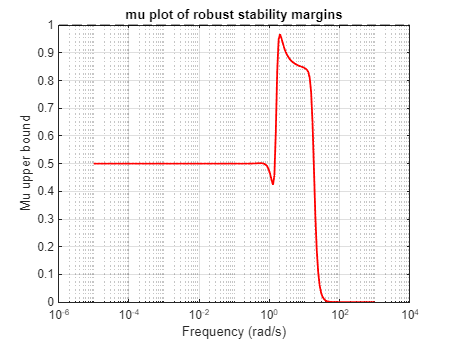

verifica_stab_robusta(G, kinf, true)

**Nota: **qui evitiamo di badare specificatamente alle performance. Le valuteremo un minimo in simulazione finale.

### Simulazione finale

Simuliamo il sistema incerto e verifichiamo che rimane stabile e che le performance sono di fatto simili a quelle sul nominale.

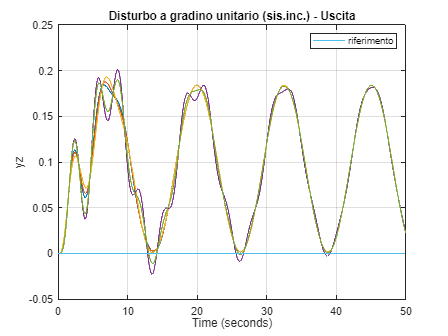

%il controllore su simulink lo settiamo noi, mentre G verrà campionato
%sulle incertezze e settato diversamente dalla funzione simulazione incerta
set_k_Sim(kinf);
simulazione_incerta(50, 'Disturbo sinusoidale (sis.inc.)', G, 5);

#### SOLUZIONE PROBLEMA 3

Il controllore che soddisfa al meglio la nostra richiesta è:

# Problema 4

### 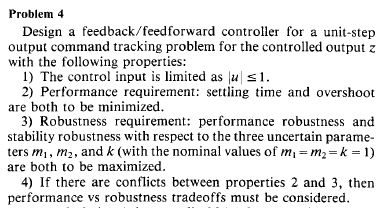

Stavolta vogliamo progettare un inseguimento a setpoint col seguente requisito: il controllo dev'essere minore di 1

Il sistema è molto difficile da controllare nei suoi parametri incerti, quindi non ci aspettiamo grandi risultati sul trade off tra performance e robustezza, soprattutto con un controllo così limitato.

Così come per il problema 2, prendiamo incertezze normalizzate, per avere una stima assoluta di robustezza

### Definizione sistema per problema 4

%parametri
m1 = ureal('m1', 1, 'PlusMinus', 1)   
m2 = ureal('m2', 1, 'PlusMinus', 1)
k = ureal('k', 1, 'PlusMinus', 1)  

%sistema
G = defG(m1, m2, k);
G_nom = minreal(G.Nominal);

### Definizione ingresso

%parametri dell'ingresso
amp_step =  1;
step_time = 0.2;

prepariamo il simulink per tale caso. Per semplicità non considereremo disturbi nella simulazione.

set_input_Sim(amp_step, step_time, 0, 0, 0, 0, 0, pw_n);

### Progetto sul nominale

Cominciamo dal progetto sul nominale. Stavolta cambiamo i pesi e diamo importanza più al riferimento che al disturbo.

%pesi soluzione
Wd = 0.1 * makeweight(10, [1 1], 0);                                    %passa basso 
Wv = 0.0001 * makeweight(0, [f_inf_rads  sqrt(2)/2], 1);                 %passa alto
Wr = makeweight(10, [1 1], 0);                                          %passa basso                           
Wy = 5;                       
Wu = 85;

P = minreal(TITO(G_nom, Wd, Wr, Wv, Wy, Wu));

16 states removed.



%Progetto Hinf
kinf = tf(minreal(hinfsyn(P, 1, 1)))


kinf =
 
       8685 s^5 + 1.739e06 s^4 + 3.167e05 s^3 + 3.499e06 s^2 + 6.069e05 s + 3.431e04
  ---------------------------------------------------------------------------------------
  s^6 + 1.025e04 s^5 + 2.024e06 s^4 + 2.711e06 s^3 + 5.092e06 s^2 + 5.356e06 s + 5.873e04
 
Continuous-time transfer function.
Model Properties

Simulo sul nominale

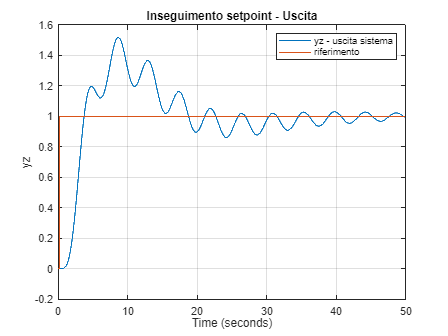

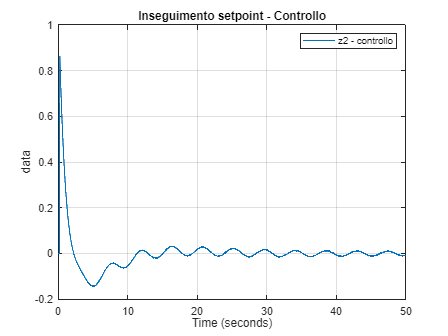

set_k_Sim(kinf);
set_G_Sim(G_nom);
simulazione(50, 'Inseguimento setpoint', [1 0 1]);

Ovviamente la limitazione sul controllo rende molto lenta la risposta, che è difficile da migliorare in termini di prestazioni.

Non abbiamo minimamente tenuto conto della robustezza, che nei precedenti problemi abbiamo visto aumentare all'aumentare del controllo e della reiezione a Wd, quindi ci aspettiamo un risultato davvero pessimo

stabmarg = struct with fields:
           LowerBound: 0.0011
           UpperBound: 0.0011
    CriticalFrequency: 1.4214


wcu = struct with fields:
     k: 1.0011
    m1: 0.9989
    m2: 0.9989


blk =      2     0
     2     0
     1     0


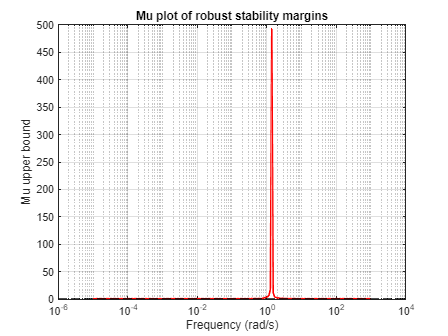

verifica_stab_robusta(G, kinf, true)

Infatti la proprietà di robustezza è totalmente assente

### Progetto robusto: va contro la richiesta di limite del controllo

Diamo più enfasi alla robustezza seguendo le linee guida dei problemi precedenti.

Si vece che l'unico modo per ottenere un briciolo di robustezza è rinunciare alle limitazioni sul controllo.

%pesi soluzione
Wd = 1000 * makeweight(10, [1 1], 0);                                    %passa basso 
Wv = 0.0001 * makeweight(0, [f_inf_rads  sqrt(2)/2], 1);                 %passa alto
Wr = 0.001 * makeweight(10, [1 1], 0);                                          %passa basso                           
Wy = 80;                       
Wu = 200;

P = minreal(TITO(G_nom, Wd, Wr, Wv, Wy, Wu));

16 states removed.



%Progetto Hinf
kinf = tf(minreal(hinfsyn(P, 1, 1)))


kinf =
 
   1.092e07 s^5 + 2.193e09 s^4 + 1.707e09 s^3 + 4.968e09 s^2 + 2.862e09 s + 8.042e08
  ------------------------------------------------------------------------------------
  s^6 + 146.9 s^5 + 1.074e04 s^4 + 4.698e05 s^3 + 1.334e07 s^2 + 2.282e08 s + 5.103e06
 
Continuous-time transfer function.
Model Properties



%verifica
verifica_stab_robusta(G, kinf)

stabmarg = struct with fields:
           LowerBound: 0.2040
           UpperBound: 0.2044
    CriticalFrequency: 1.4514


wcu = struct with fields:
     k: 0.7956
    m1: 1.2044
    m2: 1.2044


Infatti se simulo sul nominale, noto che il controllo è arrivato a ordini energetici di 10^5.

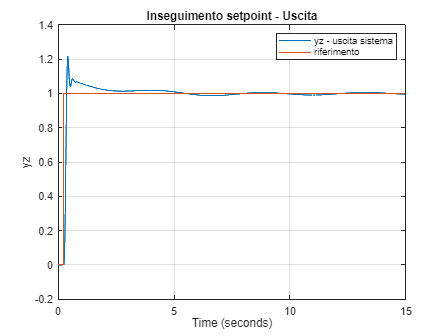

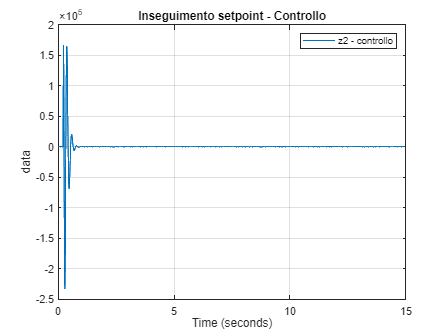

set_k_Sim(kinf);
set_G_Sim(G_nom);
simulazione(15, 'Inseguimento setpoint', [1 0 1]);

#### SOLUZIONE PROBLEMA 4

Consideriamo la richiesta della traccia **inesaudibile**, in quanto nel nostro problema si è visto empiricamente che **la robustezza è direttamente proporzionare all'energia del controllo** e un controllo limitato rende automaticamente il sistema non robusto.

### Funzioni locali

%definisce G sulla base delle variabili che gli passo
%nota: se incerto, definisce G incerto
function G = defG(m1, m2, k)
    
    %matrici
    A = [ 0 0 1 0;
          0 0 0 1;
          -k/m1 k/m1 0 0;
          k/m2 -k/m2 0 0];
    
    B = [0;
         0; 
         1/m1; 
         0];
    
    C = [0 1 0 0];
    
    D = 0;
    
    %sistema
    G = ss(A, B, C, D);
end


%crea matrice P dato i pesi
function P = TITO(G_nom, Wd, Wr, Wv, Wy, Wu)
    P = [
       -Wy*G_nom*Wd  -Wy*Wv Wy*Wr -Wy*G_nom;   
        0  0  0 Wu;   
       -G_nom*Wd  -Wv  Wr -G_nom;   
       ];
end

%effettua la conversione tra BlockStructure di nuovo tipo (restituita da lftdata), in vecchio tipo
function blk = BlockStructure_to_SimpleBlk(BlockStructure)
    %NOTA: non tengo conto della differenza tra le perturbazioni
    %reali/complesse perché il plot di mu non viene bene quando si usano reali

    blk = [];
    
    for i = 1:length(BlockStructure)

        %analizzo incertezza per incertezza
        incertezza = BlockStructure(i);
       
        if(incertezza.Size(1) == 1 && incertezza.Size(2)==1)
            %singola perturbazione, ripetuta Occurencies volte
            blk = [blk; [incertezza.Occurrences 0]];            %[r 0] perturbazioni diagonali
        else
           %Blocco quadrato ripetuto Occurencies volte
           for j = 1: incertezza.Occurrences
               blk = [blk; [incertezza.Size(1) incertezza.Size(2)]]; %[r c] perturbazioni diagonali
           end
        end
    
    end
    
    % disp("struttura delta strutturata:")
    % blk
end


%restituisce Delta (parte inc), M11 tra yd e ud e la struttura del delta
function [M11, Delta, blk] = get_M11_Delta_blk(sys)

    %separo la M (parte certa) da Delta (incertezza)
    [M, Delta, BlockStructure] = lftdata(sys);

    %estraggo M11 per valutare le performance robuste
    szDelta = size(Delta);                  % Dimensioni di Delta
    M11 = tf(M(1:szDelta(2), 1:szDelta(1)));

    %converto BlockStructure in vecchio formato, che è più gestibile
    blk = BlockStructure_to_SimpleBlk(BlockStructure);
end


% Disegna la structured singular value μ (upper bound) in scala logaritmica
function compute_plot_mu(M, blk, plot_title)
    
    % Griglia di frequenze
    omega = logspace(-5, 3, 200);
    
    % Sistema valutato sulla griglia
    M_jw = frd(M, omega);
    
    % Calcolo della mu strutturata
    mubnds = mussv(M_jw, blk, 's');

    % Se l'output è un oggetto FRD, estrai i dati numerici
    if isa(mubnds, 'frd')
        mu_upper = squeeze(mubnds.ResponseData(1,2,:));  % Upper bound
        %mu_lower = squeeze(mubnds.ResponseData(1,1,:));  % Lower bound
    else
        mu_upper = mubnds(:,2);
        %mu_lower = mubnds(:,1);
    end

    % Plot su scala logaritmica
    figure;
    semilogx(omega, mu_upper, 'r', 'LineWidth', 1.5); hold on;
    %semilogx(omega, mu_lower, 'b--', 'LineWidth', 1.5);
    yline(1, 'k--', 'LineWidth', 1.2);  % Soglia μ = 1
    grid on;
    hold off;

    % Etichette e legenda
    xlabel('Frequency (rad/s)');
    ylabel('Mu upper bound');
    title(plot_title);
    
end


%esegue una serie di istruzioni per verificare la stabiltà robusta
function verifica_stab_robusta(G, k, plot_mu_M11)

    if nargin < 3   %se non lo passo, è falso, non stampo la norma
       plot_mu_M11 = false;
    end

    %definisco ciclo chiuso incerto
    Cloop = feedback(G*k, 1);

    %margine di guadagno e caso destabilizzante più vicino
    [stabmarg,wcu] = robstab(Cloop);
    stabmarg                            %il sistema rimane stabile finché l'incertezza sta sotto il suo "stabmarg" percentuale
    wcu                                 %il primo caso che destabilizza il sistema
    
    if plot_mu_M11

        %estraggo incertezza e relazione tra yd e ud
        [M11, Delta, blk] = get_M11_Delta_blk(Cloop);

        %calcolo di mu e disegno
        compute_plot_mu(M11, blk, 'mu plot of robust stability margins');
    end
    
end


%esegue una serie di istruzioni per verificare le prestazioni robuste
function verifica_prest_robuste(FPr, Wp, toll_degrado_prestazioni)
    % Wp * Fpr: funzione di prestazione incerta e normalizzata, la cui norma dev'essere < 1 
    % toll_degrado_prest: di quanto si può tollerare in percentuale che norma > 1
    %                    (ad es se è 20%, mi va bene fino a < 1.20)

    if nargin < 3   %se non lo passo, non ho tolleranza (default 0)
       toll_degrado_prestazioni = 0;
    end


    %calcolo la norma limite sulla base della tollerenza
    norma_limite = 1 * (1 + toll_degrado_prestazioni);        %default 1
    
    %prima di calcolare le robuste, faccio un check sulle nominali
    if(norm(Wp * minreal(FPr.NominalValue), "inf") > norma_limite) 
        disp("Norma della nominale non è <" + num2str(norma_limite) + ". Questa è condizione necessaria per le performance robuste")
    else    
        %istruzioni matlab
        opt = robOptions('Display','on');
        [perfmarg,wcu] = robgain(Wp * FPr, norma_limite,opt)
       
    end
end


%imposta variabili circuito simulink
function set_k_Sim(k)      

    assignin('base', 'k_simulink', k);    
    
end

function set_G_Sim(G)      

   assignin('base', 'G_simulink', G);
  
end
    
function set_input_Sim(rsa, rst, dsa, dst, dwa, dwf, dwp, pwn)      

    % Gradino a riferimento
    assignin('base', 'reference_step_amplitude', rsa);
    assignin('base', 'reference_step_time', rst);
    
    % Gradino a disturbo
    assignin('base', 'd_step_amplitude', dsa);
    assignin('base', 'd_step_time', dst);

    % Sinusoide a disturbo
    assignin('base', 'd_sinewave_amplitude', dwa);
    assignin('base', 'd_sinewave_frequency_Hz', dwf);
    assignin('base', 'd_sinewave_phase_rad', dwp);
    
    % Rumore di misura
    assignin('base', 'power_v_noise', pwn);
end


function simulazione(Tsim, titleText, print_flags) 

    model = 'simulatoreBP';
    load_system(model);
    set_param(model, 'StopTime', num2str(Tsim));
    out = sim(model);
    
 
    % Grafico uscita e riferimento
    if(print_flags(1))
        figure;
        plot(out.yz, 'DisplayName', 'yz - uscita sistema');
        hold on;
        
        plot(out.rif, 'DisplayName', 'riferimento');
        hold off;
    
        title([titleText, ' - Uscita']);
        legend;
        grid on;
    end

    % Grafico errore
    if(print_flags(2))
        figure;
        plot(out.y, 'DisplayName', 'z1 - errore');
        title([titleText, ' - Errore']);
        legend;
        grid on;
    end

    % Grafico controllo
    if(print_flags(3))
        figure;
        plot(out.u, 'DisplayName', 'z2 - controllo');
        title([titleText, ' - Controllo']);
        legend;
        grid on;
    end
end


%fa delle simulazioni con G, incerta, con num_samples tentativi
function simulazione_incerta(Tsim, titleText, G_incerta, num_samples)

    %preparo simulazione
    model = 'simulatoreBP';
    load_system(model);
    set_param(model, 'StopTime', num2str(Tsim));

    %genero un numero di modelli incerti per la simulazione
    inc_values = usample(ufind(G_incerta), num_samples); % array di modelli SS


    %simulo tutti i modelli
    figure;
    for i = 1:num_samples
    
        %setto la G a uno dei modelli incerti
        incertezza = inc_values(i);
        G_i = usubs(G_incerta, incertezza);
        G_i = tf(minreal(G_i));
        set_G_Sim(G_i);


        %simulo
        out = sim(model);
        h = plot(out.yz);
        h.Annotation.LegendInformation.IconDisplayStyle = 'off';

        hold on;
       
    end

    plot(out.rif, 'DisplayName', 'riferimento');
    hold off;

    title([titleText, ' - Uscita']);
    legend;
    grid on;
 

end


function kinf_red = riduciControllorePerEnergia(kinf, sogliaEnergia)
% Riduce il controllore kinf mantenendo energia ≥ sogliaEnergia (es. 0.99)

    if nargin < 2
        sogliaEnergia = 0.99;  % default 99%
    end

    % 1. Hankel singular values
    hsv = hsvd(kinf);

    % 2. Energia cumulata normalizzata
    cumEnergia = cumsum(hsv) / sum(hsv);

    % 3. Trova ordine minimo che supera la soglia
    order_chosen = find(cumEnergia >= sogliaEnergia, 1);

    % 4. Riduzione automatica con balred
    kinf_red = balred(kinf, order_chosen);

    % 5. Energia effettivamente mantenuta
    energy_ratio = cumEnergia(order_chosen);

    % 6. Messaggio riepilogo
    fprintf('Ordine scelto: %d (Energia mantenuta: %.4f)\n', order_chosen, energy_ratio);
end





# Autore e proprietario del progetto

**Studente: **Schettini Francesco (A180000485)

**Corso di studi: **Ingegneria informatica magistrale - ramo automatica

**Esame e docente: **Robust Control - Ing. Alberto Cavallo.

**Università: **Università degli studi della Campania - Luigi Vanvitelli

**Reference GitHub: **[GitHub - francesco1203/RobustControl](https://github.com/francesco1203/RobustControl)